## Case Study: Modeling Race Car Motion

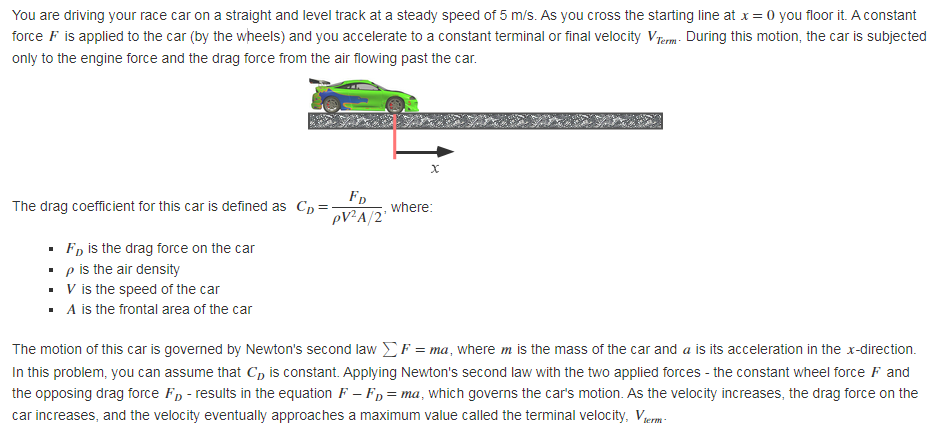

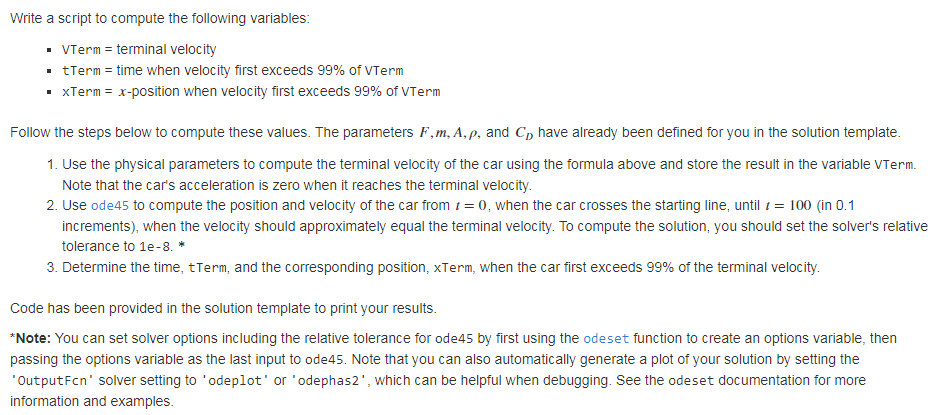

% Define the problem parameters.
F = 4000.0;            % force on car,     [N]
m = 1300.0;            % mass of car,      [kg]
A = 3.0;               % frontal area,     [m^2]
Cd = 0.6;              % drag coefficient, [-]
rho = 1.23;            % air density,      [kg/m^3] 

% Compute the terminal velocity.
VTerm = sqrt(F/(Cd*rho*A/2))

VTerm = 60.1113


% Define a derivative function for the ODE problem.
%Sabemos que F-Fd=ma y esto a la vez es F-(Cd/(rho*A/2*v^2))=m*a
%V=x' y a=x'', entonces tenemos F-(Cd*(rho*A/2*x'))=m*x''
% sea v=x1'=x2, entonces x2'=a
%Se obtiene x1'=x2, x2'=(F-Cd*rho*(A/2)*x1')/m
f=@(t,x) [x(2); (F-Cd*rho*(A/2)*(x(2)^2))/m];

% Create an ODE options structure to set the solver relative tolerance.
options=odeset('RelTol',1e-8);

% Solve the car motion ODE problem using ODE45.
t=0:1:100;
x0=[0;5];
[t velPos]=ode45(f,t,x0,options)

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


velPos = 	1.0e+03 *

         0    0.0050
    0.0065    0.0080
    0.0161    0.0110
    0.0286    0.0140
    0.0440    0.0169
    0.0623    0.0196
    0.0833    0.0223
    0.1069    0.0249
    0.1331    0.0274
    0.1618    0.0298



% Find where the velocity first exceeds 99% of its terminal velocity.
indx=min(t(velPos(:,2)>0.99*VTerm))

indx = 51

tTerm = indx 

tTerm = 52

xTerm = velPos(indx,1)

xTerm = 2.2913e+03